Spherical Spiral

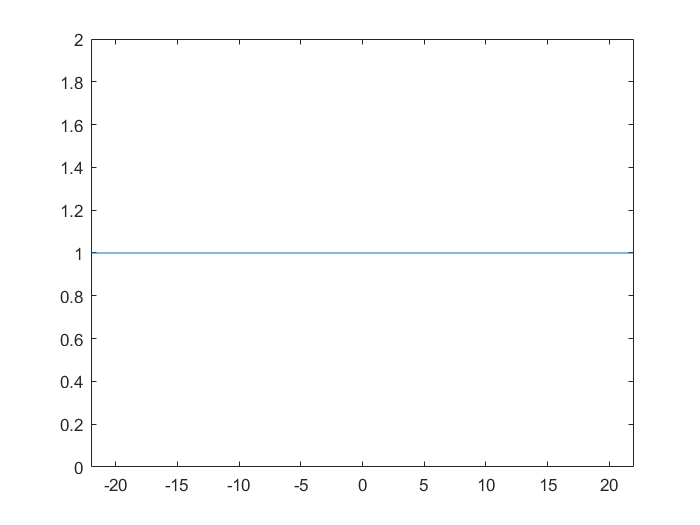

syms t f1(t) f2(t) f3(t) x y z 
N = 7;  % number of periods to plot...
a = 0.1;    % any nonzero number will do...
f1(t)=cos(t)/sqrt(1+a^2*t^2);
f2(t)=sin(t)/sqrt(1+a^2*t^2);
f3(t)=a*t/sqrt(1+a^2*t^2);
normf(t)=sqrt(f1^2+f2^2+f3^2);  % This is the distance from (x,y,z) to the origin
fplot(normf,[-N*pi N*pi]);      % Oh look, the distance is consant ... 1 ; therefore on sphere of radius 1

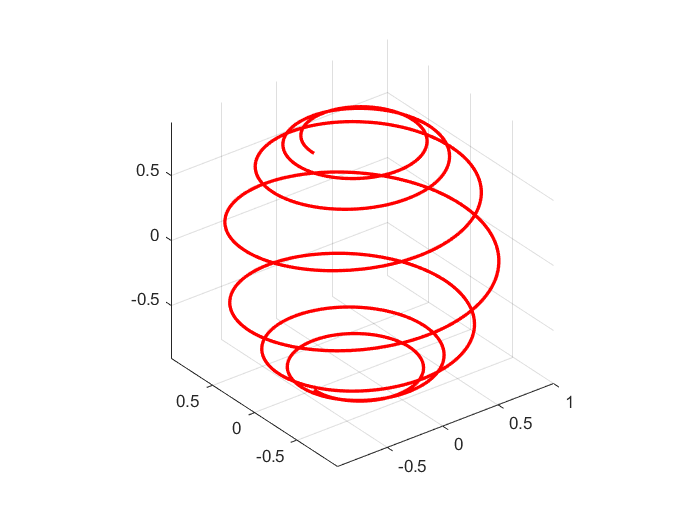

fplot3(f1,f2,f3,[-N*pi N*pi],'r','LineWidth',2); axis square;

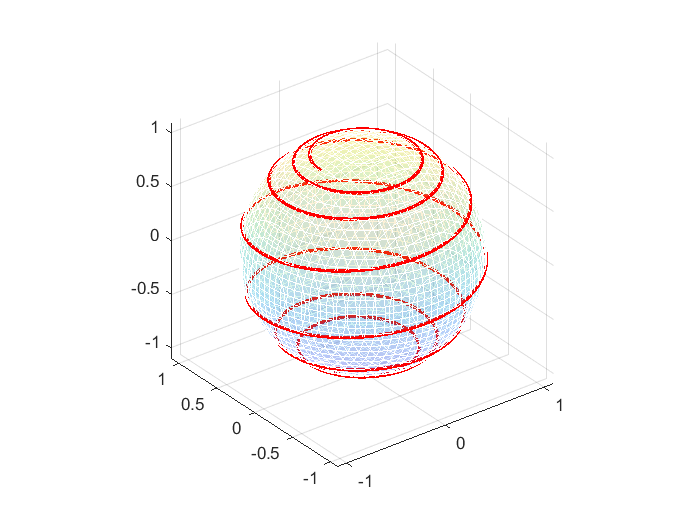

figure; % and now let's see the sphere...
    fplot3(f1,f2,f3,[-N*pi N*pi],'r','LineWidth',2); hold on;
    fimplicit3(1-(x^2+y^2+z^2),'FaceAlpha',0.2,'EdgeColor','w'); 
    axis square; 
hold off;